% Select the NR-TM or PDSCH FRC waveform parameters
dlnrref = "NR-FR1-TM3.1";  % Model name and properties
bw      = "100MHz";  % Channel bandwidth
scs     = "30kHz";  % Subcarrier spacing
dm      = "FDD";  % Duplexing mode
ncellid = 1;  % NCellID
sv      = "15.2.0";  % TS 38.141-x version (NR-TM only)

% Run this entire section to generate the required waveform
   

% Create generator object for the above NR-TM/PDSCH FRC reference model
dlrefwavegen = hNRReferenceWaveformGenerator(dlnrref,bw,scs,dm,ncellid,sv);
% Generate waveform
[dlrefwaveform,dlrefwaveinfo,dlresourceinfo] = generateWaveform(dlrefwavegen);

% View transmission information about the set of PDSCH within the waveform
dlresourceinfo.WaveformResources.PDSCH

ans = 包含以下字段的 1×2 struct 数组:
    Name
    CDMLengths
    Resources



% View detailed information about one of the PDSCH sequences
dlresourceinfo.WaveformResources.PDSCH(1).Resources

ans = 包含以下字段的 1×20 struct 数组:
    NSlot
    TransportBlockSize
    TransportBlock
    RV
    Codeword
    G
    Gd
    ChannelIndices
    ChannelSymbols
    DMRSSymbolSet
    DMRSIndices
    DMRSSymbols
    PTRSSymbolSet
    PTRSIndices
    PTRSSymbols



% Waveform sampling rate (Hz)
samplingrate = dlrefwaveinfo.Info.SamplingRate  

samplingrate = 122880000

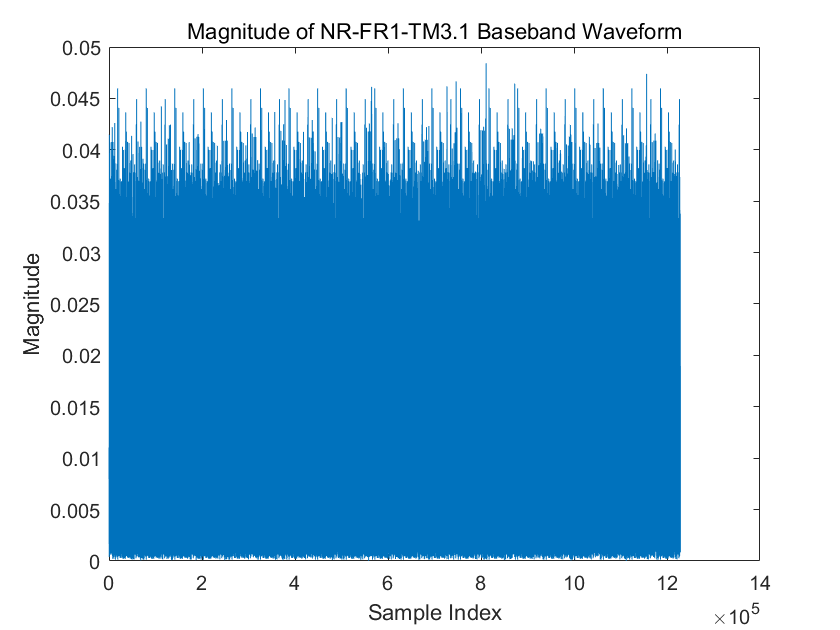


plot(abs(dlrefwaveform)); title(sprintf('Magnitude of %s Baseband Waveform',dlnrref)); xlabel('Sample Index'); ylabel('Magnitude');

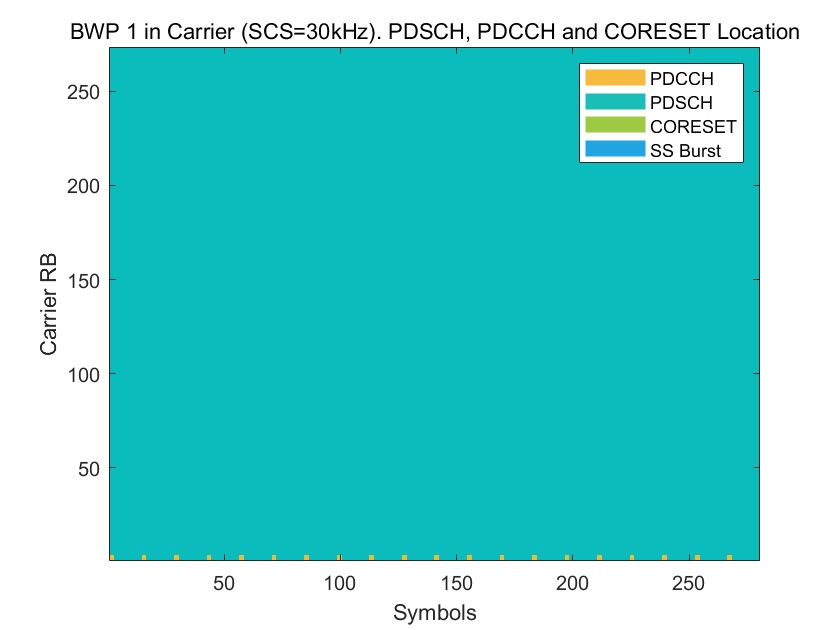

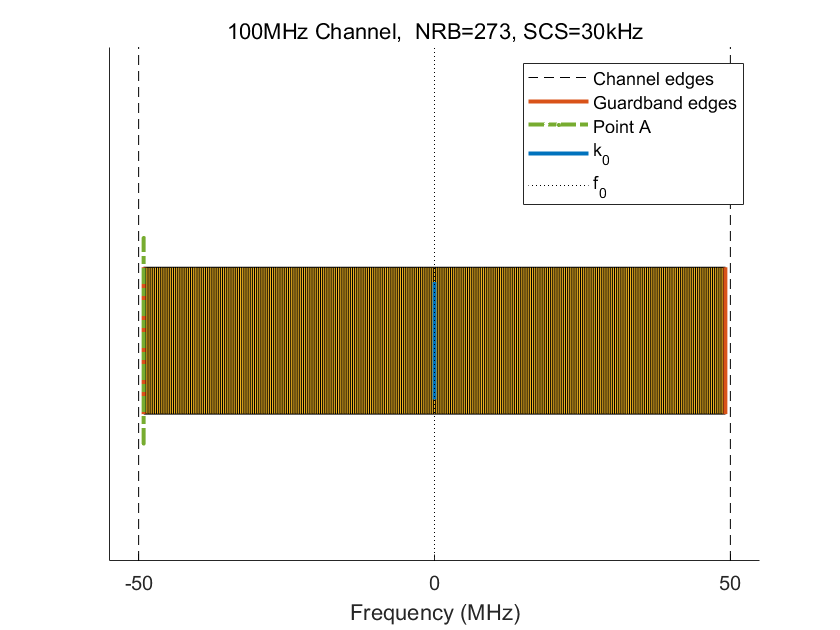

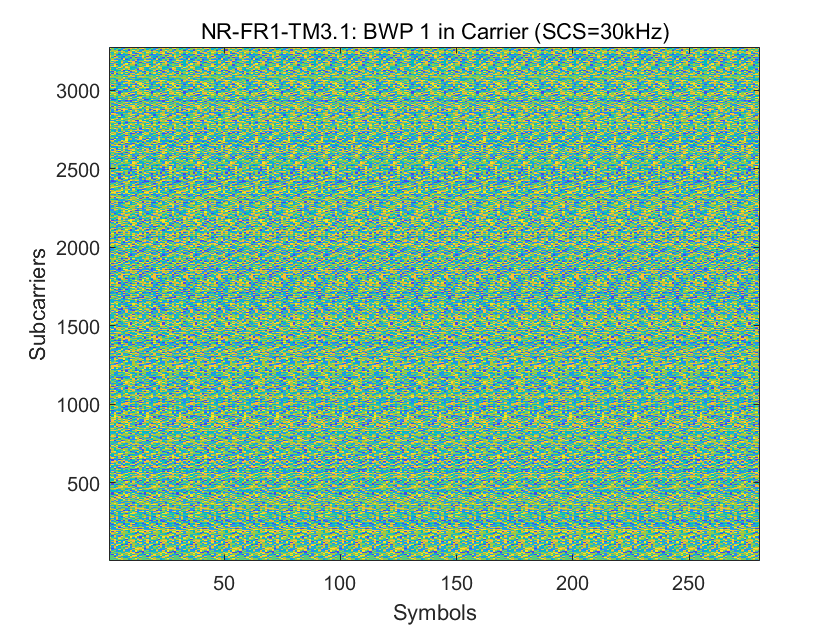


% Visualize the associated PRB and subcarrier resource grids
displayResourceGrid(dlrefwavegen);


dlrefwaveform = dlrefwaveform';
maximum = max( [ real( dlrefwaveform) imag( dlrefwaveform ) ] );
dlrefwaveform = 0.7 * dlrefwaveform / maximum;

dlrefwaveform = [real(dlrefwaveform);imag(dlrefwaveform)]; % get the real and imaginary parts
dlrefwaveform = dlrefwaveform(:)';    % transpose and interleave the waveform


 filename = strcat(dlnrref,'_',dm,'_', bw, '_','fs',num2str(dlrefwaveinfo.Info.SamplingRate),'.txt')

filename = "NR-FR1-TM3.1_FDD_100MHz_fs122880000.txt"

fid = fopen(filename, 'w');
fprintf(fid, '%d\n', dlrefwaveinfo.Info.SamplingRate);
for i = 1:length(dlrefwaveform)
    fprintf(fid, '%d\n', dlrefwaveform(i));
end
fclose(fid);
